

clc
close all
clear

## ROUTE MAPPING


% Get coordinates of Mawson Station
Mawson_coords = scarloc('mawson station');
Spatial_res = 10;
% Create a map centered on Mawson Station

figure('Position', [100, 100, 1200, 800]);
mapzoomps(Mawson_coords(1), Mawson_coords(2), 'size', [100 100], 'frame', 'off','km');
hold on;
scatterps(Mawson_coords(1), Mawson_coords(2), 10,'Marker', 'd', 'MarkerFaceColor', 'r');
scarlabel('Mawson Station');
title('Step 1: Select the waypoints along the route');
% Customize the plot as needed
box on;
scalebarps;

[bed,lat,lon] = bedmachine_data('bed',xlim,ylim,'geo');
pcolorps(lat, lon, bed);
bedmachine('surface', 'contour', 0:100:5000);
colorbar;
hold off;
% Get waypoints interactively
disp('Select waypoints on the map. Press enter when done :)');

Select waypoints on the map. Press enter when done :)


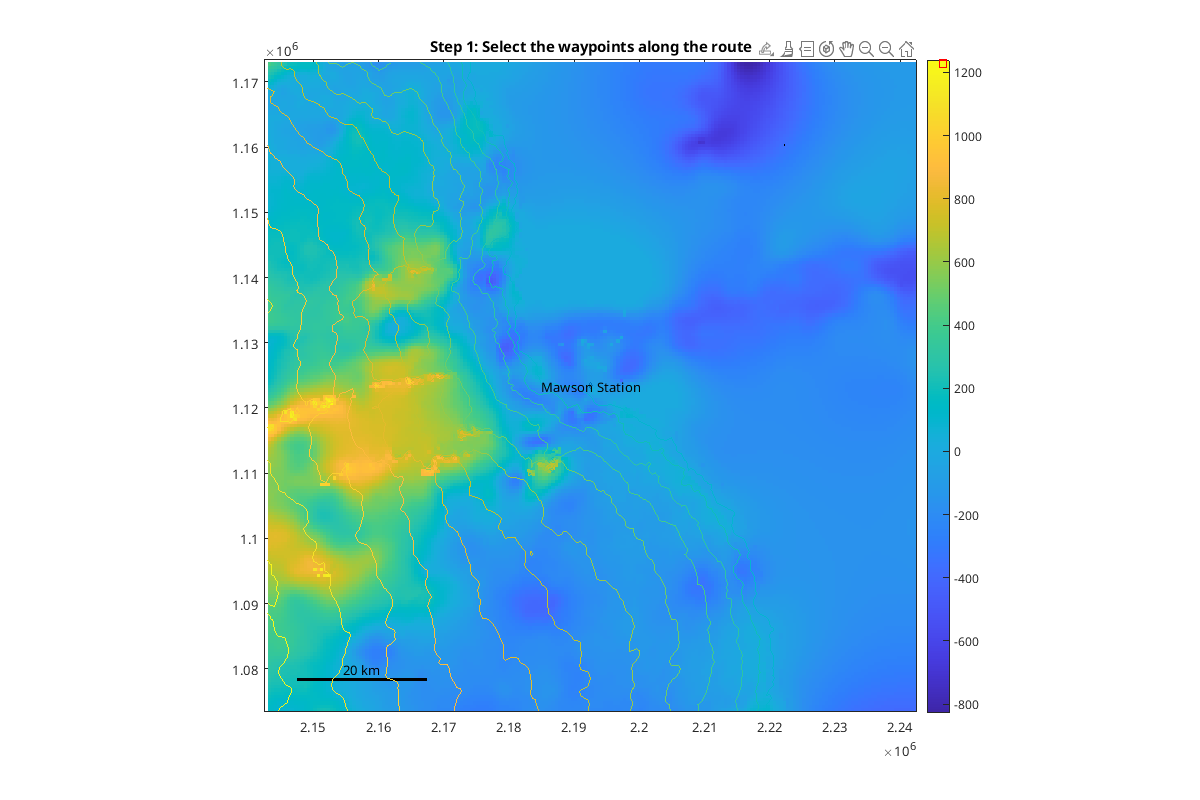

[lat,lon] = coord;

% Assign start and end points
startlat = lat(1);
startlon = lon(1);
endlat = lat(end);
endlon = lon(end);
intermediatewaypoints = [lat(2:end-1) lon(2:end-1)];
waypoints = [startlat startlon; intermediatewaypoints; endlat endlon];
[lati,loni] = pspath([startlat endlat],[startlon endlon],Spatial_res);  %gives interpolated points between the specified waypoints
linpath = [lati ; loni]';       
path = [startlat,startlon];

% Initialize cell arrays to store latitude and longitude
path_lat = startlat;
path_lon = startlon;

for k = 1:height(waypoints)
    if k < height(waypoints)
        [interlat, interlon] = pspath([waypoints(k,1) waypoints(k+1,1)], [waypoints(k,2) waypoints(k+1,2)], Spatial_res);
        
        % Append new latitude and longitude values
        path_lat = [path_lat; interlat'];
        path_lon = [path_lon; interlon'];
    end
end

% Concatenate latitude and longitude arrays
path = [path_lat, path_lon];

d = pathdistps(path(:,1)', path(:,2)', 'km')';
z = bedmachine_interp('surface', path(:,1)', path(:,2)')';
%figure;
% Subplot 2: Plot of Distance traveled vs Surface elevation
%plot(d, z)
%xlabel 'Distance traveled (km)'
%ylabel 'Surface elevation (m)'
%grid on

% Convert distance to meters
d_meters = d*1000;  % Convert kilometers to meters

%envdata=ncdataset('env_data.grib')

% Subplot 3: Plot of Slope vs Distance traveled
%subplot(2, 2, 2);

% Calculate slope (gradient) using finite differences
%dz = diff(z);  % Calculate difference in elevation
%dd = diff(d_meters);  % Calculate difference in distance (in meters)
%slope = dz ./ dd;  % Calculate slope

% Plot the slope
%plot(d_meters(2:end), slope)
%xlabel 'Distance traveled (meters)'
%ylabel 'Slope (%)'
%grid on

## SLICER FUNCTION AND VELOCITY PROFILER


% Subplot 4: Interactive Elevation Profile Slicer
figure
plot(d_meters, z)
xlabel 'Distance traveled (meters)'
ylabel 'Surface elevation (m)'
grid on

title('Step 2: Interactive elevation profile slicer');
disp('Select slicepoints on the plot. Right-click when done :)');

Select slicepoints on the plot. Right-click when done :)


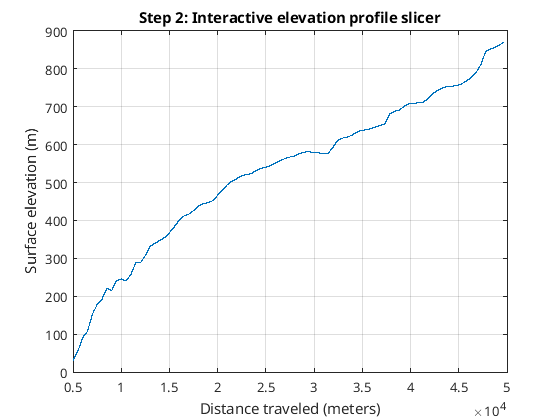

[slicepoints_x, ~] = ginput();

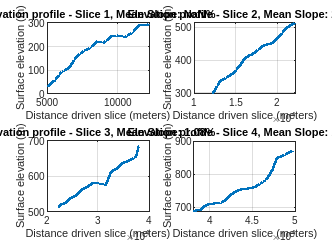

endslice_x = d_meters(end);
endslice_y = z(end);

num_slices = length(slicepoints_x) + 1;

% Calculate the number of rows and columns for the subplot grid
cols = ceil(sqrt(num_slices));
rows = ceil(num_slices / cols);

% Create a figure with a subplot grid
figure

% Cell array to store slice-specific data
slice_data = cell(num_slices, 2);
mean_slopes = zeros(num_slices, 1);  % Store slopes in a column vector
for i = 1:num_slices
    if i == 1
        % for the first slice, start from the real distance
        start_distance = 0;
    else
        % for subsequent slices, start from the end of the previous slice
        start_distance = slice_data{i-1, 1}(end);
    end
    
    % handle the last slice differently
    if i == num_slices
        end_distance = endslice_x;
    else
        end_distance = slicepoints_x(i);
    end
    
    % find indices corresponding to the selected slice
    [~, start_index] = min(abs(d_meters - start_distance));
    [~, end_index] = min(abs(d_meters - end_distance));

    % Extract the elevation and distance data for the slice
    slice_data{i, 1} = d_meters(start_index:end_index);
    slice_data{i, 2} = z(start_index:end_index);

    % adjust distance to start from the real distance
    slice_data{i, 1} = slice_data{i, 1} - slice_data{i, 1}(1) + start_distance;

    % calculate the mean slope for the slice in percentage
    elevation_change = slice_data{i, 2}(end) - slice_data{i, 2}(1);
    distance_driven = slice_data{i, 1}(end) - slice_data{i, 1}(1);
    mean_slope = (elevation_change / distance_driven) * 100;
    mean_slopes(i) = mean_slope;  % Store mean slope in the column vector
    
    % calculate the subplot index based on the current iteration
    subplot(rows, cols, i);
    plot(slice_data{i, 1}, slice_data{i, 2}, 'LineWidth', 2);
    xlabel 'Distance driven slice (meters)'
    ylabel 'Surface elevation (m)'
    title(['Elevation profile - Slice ', num2str(i), ', Mean Slope: ', num2str(mean_slope, '%.2f'), '%']);
    grid on
end


slice_velocities = zeros(1, num_slices);
for i = 1:num_slices
    % prompt the user to enter the velocity profiles per slice
    prompt = ['Enter velocity for Slice ', num2str(i), ' (in km/h): '];
    slice_velocities(i) = input(prompt);
end


## timesim calcs

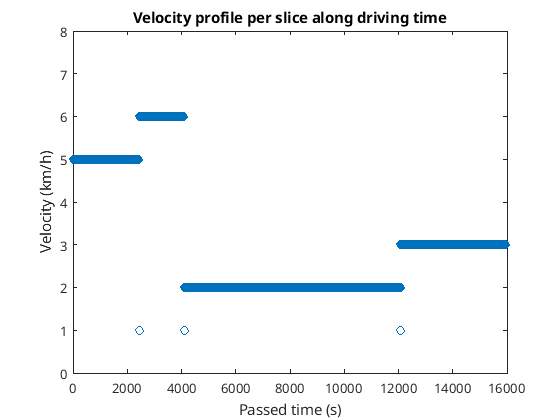

clear slice_times
slice_times = zeros(1, num_slices);
% ugly ass coding sorry
total_travel_time = 0;
for i = 1:num_slices
    distance_driven = slice_data{i, 1}(end) - slice_data{i, 1}(1);
    travel_time = distance_driven / slice_velocities(i);
    slice_times(i) = travel_time;
    total_travel_time = total_travel_time + travel_time;
end

vel_times = ones(length(time_vector), 1);

current_time = 0;
for i = 1:num_slices
    slice_duration = ceil(slice_times(i));
    slice_vel = slice_velocities(i);
    
    for j = 1:slice_duration
        vel_times(current_time + j) = slice_vel;
    end
    
    % Update the current time
    current_time = current_time + slice_duration;
    vel_times = vel_times(3:1:length(vel_times));
end
plot(time_vector,vel_times,'o')
ylim([0 max(slice_velocities)+2]);
ylabel('Velocity (km/h)');
xlabel('Passed time (s)');
title('Velocity profile per slice along driving time')

%sim("Mass_est.slx")
%open("Mass_est.slx")

